**The Tabular value-function methods on the cart and pole system**

Consider the cart-and-pole system here depicted:

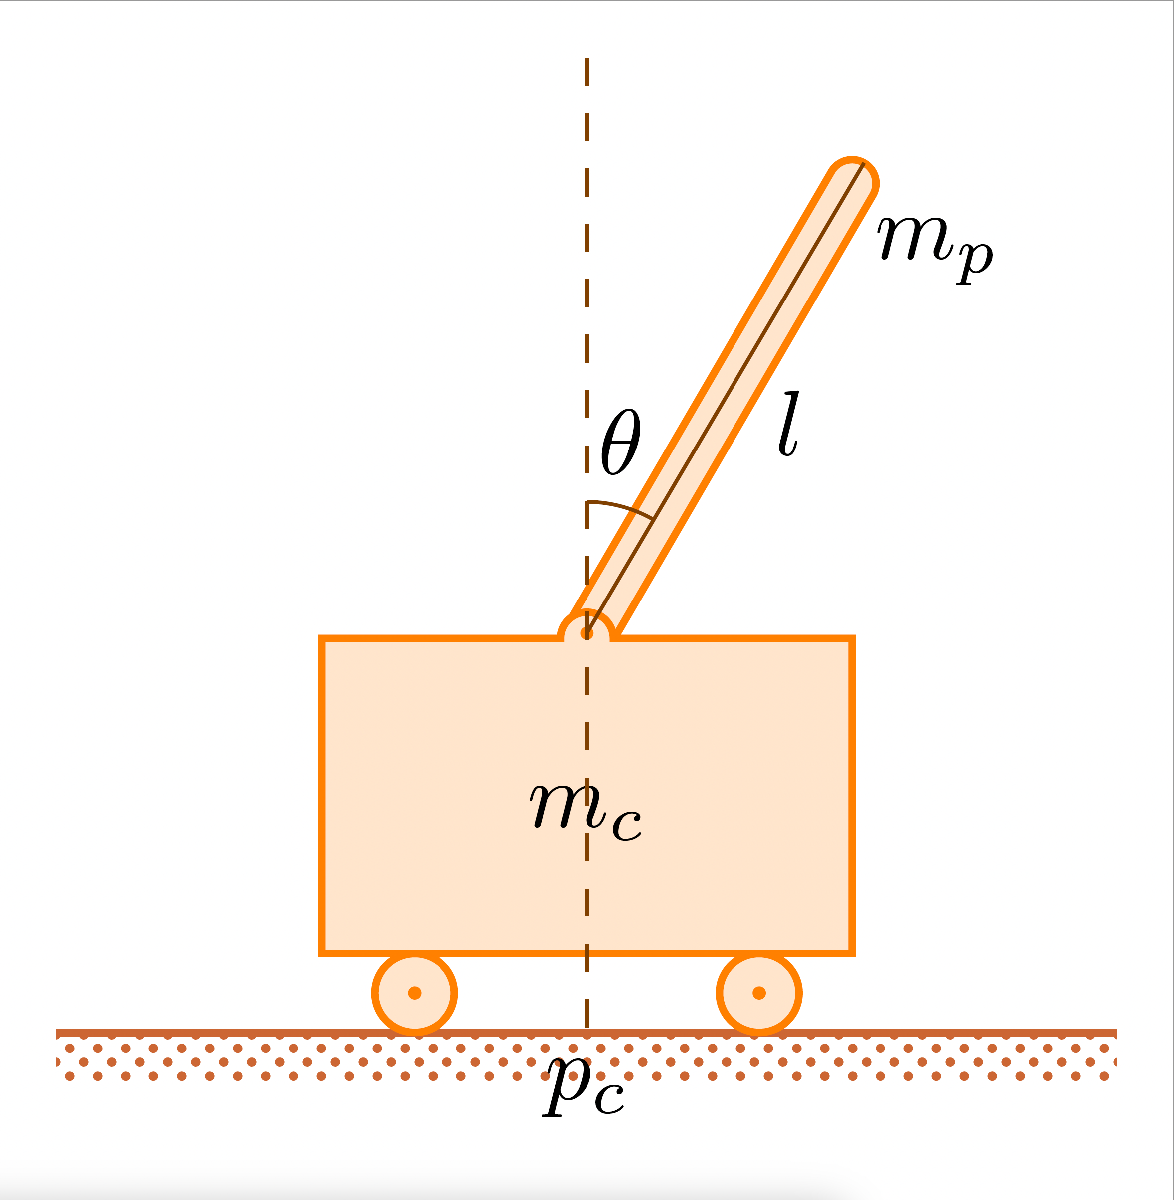

whose dynamics follows the following equations:


$$\ddot{\theta}=\frac{g \sin(\theta)\,+\,\cos(\theta) \left[ \frac{-F\,-\,m_p\,l\,\dot{\theta}^2 \sin \left(\theta\right)\,+\,\mu_c\,\text{sgn}\left(\dot{p}_c\right)}{m_c\,+\,m_p}\right]-\frac{\mu_p\dot{\theta}}{m_p\,l}}{l\,\left[\frac{4}{3}-\frac{m_p\,cos^2\left(\theta\right)}{m_c\,+\,m_p}\right]}$$
   


$$(*)$$



$$  \ddot{p}_c=\frac{F\,+\,m_p\,l\,\left[\dot{\theta}^2\,\sin\left(\theta\right)\,-\,\ddot{\theta}\,\cos(\theta)\right]}{m_c\,+\,m_p}$$


where $g = 9.8\,\text{m/sec}$ is the gravitational acceleration, $m_c = 1\,\text{kg}$ is the cart mass, $m_p = 0.1\,\text{kg}$ is the pole mass, $l = 0.5\,\text{m}$ is the half-pole length, $\mu_p = 0.000002$ is the pole on cart friction coefficient.

1. Given the $$\mathcal{X}$$, $$\mathcal{U}$$ of the first hands-on define: the set of possible initial conditions of an episode; the terminal conditions of the episode

**ANSWER 1:**

Let us recall what an episode is:

An **episode** is a finite-time simulation of a system subject to a controller $\pi$, which starts from an initial condition $x^{\left(0\right)}$ and ends when a **terminal condition** is satisfied:

- $x^{\left(k\right)} =x_{\textrm{des}}$ is reached

- the maximum number of time steps has been executed

Furthermore, we recall that in HandsOn1 we defined the state and control input domains as follows:

    $X=\left\lbrace x=\left\lbrack \begin{array}{c}
\theta \\
\dot{\theta} \\
p_c \\
\dot{p_c } 
\end{array}\right\rbrack \;\in R^{\;4} \;\textrm{such}\;\textrm{that}\;|\theta |\le \frac{\pi }{2},|\dot{\theta} |\le 20,|p_c |\le 3,|\dot{p_c |} \le 5\right\rbrace$    ;    $U=\left\lbrace u\in R\;\textrm{such}\;\textrm{that}\;u\in \left\lbrack -10,10\right\rbrack \right\rbrace$

The **set of initial conditions**, therefore, is the set of all possible values that our state vector can take, but we restrict the limits even further to ensure that our agent has initial conditions as close as possible to the equilibrium point. In this regard, we define the following set of possible initial conditions:


$$X_0 =\left\lbrace x_0 =\left\lbrack \begin{array}{c}
\theta^{\left(0\right)} \\
{\dot{\theta} }^{\left(0\right)} \\
p_c^{\left(0\right)} \\
{\dot{p_c } }^{\left(0\right)} 
\end{array}\right\rbrack \in R^{\;4} \;\textrm{such}\;\textrm{that}\;|\theta^{\left(0\right)} |\le 12\degree ,\;|{\dot{\theta} }^{\left(0\right)} |=0,\;|p_c^{\left(0\right)} |\le 2\ldotp 4,\;|{\dot{p_c } }^{\left(0\right)} |=0\right\rbrace$$


The **terminal conditions**, therefore, will be those conditions under which the episode ends:

- the state exceeds the imposed limits

- the time steps are terminated

2. Provide a proper discretization of the state space $$\mathcal{X}$$, and define the size of the action-value function $Q$

**ANSWER 2:**

Below is the MATLAB code we wrote, in which we will define the limits only for the state variables representing the pole angle and the cart position `(theta, p_c)`. We will then define the **discretised state space**, presenting a finer discretisation towards the centre and then enlarging the intervals as we move away from the equilibrium position.

As suggested in class, we will also define two external intervals that allow us to update the `Q_table` even in the event of an episode failure.

clear
clc
close all

% let's define the physical parameters
par.g = 9.8;
par.m_c = 1.0;
par.m_p = 0.1;
par.l = 0.5;
par.mu_c = 0.0005;
par.mu_p = 0.000002;

% actions
par.actions = [-10,10];                 % [left force, right force]
par.n_actions = length(par.actions);

% --- let's define the DISCRETE SPACE ---

% let's define the limits for the TERMINAL CONDITIONS
theta_limit = deg2rad(12);       % +/- 12 grades
p_c_limit = 2.4;                 % +/- 2.4 meters

% let's discretise

% Pole angle (x(1))
dis_theta = [-12, -6, -1, 1, 6, 12];
confini_theta   = [-inf, deg2rad(dis_theta), inf];

% Angular Velocity (x(2))
confini_theta_1 = [-inf, -1.5, -0.25, 0.25, 1.5, inf]; % 0.25 rad/s --> approximately 14.32 deg/s
                                                       % 1.50 rad/s --> approximately 85.94 deg/s

% Cart Position (x(3))
confini_p_c     = [-inf, -2.4, -0.8, 0.8, 2.4, inf];

% Cart Velocity (x(4))
confini_p_c_1   = [-inf, -0.5, 0.5, inf];

% Number of intervals of individual variables
n_theta   = length(confini_theta)-1;
n_theta_1 = length(confini_theta_1)-1;
n_p_c     = length(confini_p_c)-1;
n_p_c_1   = length(confini_p_c_1)-1;

% states dimension
n_state = [n_theta ,n_theta_1, n_p_c, n_p_c_1];

% define the size of the Q-TABLE and print the LIMITS
fprintf('Terminal limits: Angle = %.2f rad, Position = %.1f m', theta_limit, p_c_limit);

Terminal limits: Angle = 0.21 rad, Position = 2.4 m

fprintf('Q-Table size: [%d, %d, %d, %d, %d]' , n_theta , n_theta_1 , n_p_c , n_p_c_1 , par.n_actions);

Q-Table size: [7, 5, 5, 3, 2]

3. Create a code able to select the discretized version of a measured state $x$

**ANSWER 3:**

We present a function we wrote, `indiceStato()`, which returns the discrete index of each continuous value in the state vector. A more detailed description, as well as the code for this* local function*, can be found at the end of this Live Script, which, as in all previous HandsOns, lists the local functions used in the code.

% --- DISCRETISATION TEST ---
test_x = [0.1, -0.5, 0.2, 1.0];    % x = [theta, theta_1, p_c, p_c_1]
test_idx_vec = indiceStato(test_x);

fprintf('Continuous states: [%.2f, %.2f, %.2f, %.2f]', test_x);

Continuous states: [0.10, -0.50, 0.20, 1.00]

fprintf('Discrete indexes: [%d, %d, %d, %d]', test_idx_vec(1), test_idx_vec(2), test_idx_vec(3), test_idx_vec(4));

Discrete indexes: [5, 2, 3, 3]

4. Given the terminal conditions of the episode (selected in 1.) create a code able to perform a fixed number of episodes of a fixed number of steps, starting from random initial conditions and applying random inputs.

**ANSWER 4:**

What we are going to do in the MATLAB code presented below is a for loop that allows us to:

- At the beginning of each episode, the pendulum is returned to the vertical position with a small random perturbation

- A second for loop then begins, which will last `for` a maximum number of steps equal to `max_steps`

- At each instant, an input is chosen at random (-10 or +10) without looking at the `Q_table`

- Then, the local `simulatore` function is called: the input force is applied, the dynamics are calculated, and we are shown where the system will end up

- The agent checks whether the system goes outside the limits and, if so, the simulation is interrupted, then the exit from the for loop is forced with the `break` command

% --- EXECUTION OF RANDOM EPISODES ---

% Parameters for Reinforcement Learning
Ts = 0.02;                 % Sampling time (step)
max_steps = 1000;          % Maximum steps before ‘winning’ the episode
num_episodes = 80000;      % Number of episodes for training 

alpha = 0.05;              % Learning rate
gamma = 0.995;             % Discount factor
epsilon_start = 1.0;       % Initial epsilon (100% exploration)
epsilon_min = 0.001;       % Minimum epsilon

epsilon_decay = (epsilon_min / epsilon_start)^(1 / (num_episodes * 0.85));

% Duration of the event to be checked --> 0.02*1000 = 20 seconds
%                                       
% OBS.                                --> This ensures that the check is not just a coincidence, 
%                                         due to the fact that the event lasts too short a time. 

n_episode_random = 5;      % number of random episodes

for ep = 1:n_episode_random
        
        % random initial state
        x_0 = stato_iniziale();
        
        for step = 1:max_steps
            % Select a random action
            action = randi(par.n_actions); 
            
            % Perform the step
            [x_k_1, ~] = simulatore(x_0, action, par, Ts, theta_limit, p_c_limit);
            
            x_0 = x_k_1;
            
            if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
                fprintf('Episode %d completed (failure) at step %d\n', ep, step);
                break;
            end
            
            if step == max_steps
                fprintf('Episode %d completed (success) at step %d\n', ep, step);
            end
        end
end

Episode 1 completed (failure) at step 20
Episode 2 completed (failure) at step 18
Episode 3 completed (failure) at step 36
Episode 4 completed (failure) at step 18
Episode 5 completed (failure) at step 31


5. Create a function able to perform $$\epsilon$$-greedy policy for a chosen $$\epsilon$$.

**ANSWER 5:**

In order to reduce the execution time of the following code, I tried to implement the functions that had `Q_table` as a parameter directly within the `for` loop of the *Tabular Q-Learning algorithm* where we will use them.

However, the function required by the exercise could be written as follows (the `epsilon_greedy_policy()` function has been written as a comment for the reason mentioned above):

% epsilon_greedy_policy  --> allows us to resolve the Explore vs Exploit trade-off
%                           
% What we do:            --> 1. A random number is chosen
%                            2. If this number is less than eps, then a random action is chosen
%                            3. Otherwise, the Q-table is looked at and the maximum value is chosen

%function action_idx = epsilon_greedy_policy(Q_table, state_idx, epsilon)
%    if rand() < epsilon
%        % Exploration: choose a random action
%        action_idx = randi(2);
%    else
         % Exploitation: choose the best action (highest Q value)
%        [~, action_idx] = max(Q_table(state_idx, :));
%    end
%end

6. Create a code that applies Tabular Q-Learning algorithm.

**ANSWER 6:**

Let us recall the theory studied, in order to best present the following MATLAB code describing a *Tabular Q-Learning algorithm*:

**Q-Learning** is an ***Off-Policy Algorithm***, which means that the evaluation is based on *greedy policy*.

INITIALISATION: the matrix is initialised $Q\;\;\;\;\forall x\in X\;\;\;\forall u\in U$

FOR EACH EPISODE, REPEAT THE FOLLOWING STEPS:

- set the initial state $x^{\left(0\right)}$

- repeat for each step of the episode until we encounter a terminal condition:

                  -    select an action $u^{\left(k\right)}$ with $\varepsilon -\textrm{greedy}\;\textrm{policy}$

                  -    perform the action $u^{\left(k\right)}$, observe $x^{\left(k+1\right)}$ e $r^{\left(k+1\right)}$

                  -    $Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)=Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)+\alpha \left\lbrack r^{\left(k+1\right)} +\gamma \textrm{maxQ}\left(x^{\left(k+1\right)} ,u\right)-Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)\right\rbrack$   

                  -    update $x^{\left(k\right)} =x^{\left(k+1\right)}$    

% Q-Learning initialisation
eps = epsilon_start;
Q_table_opt = zeros(n_theta ,n_theta_1, n_p_c, n_p_c_1, par.n_actions);
rewards_per_episode = zeros(num_episodes, 1);
    
for ep = 1:num_episodes
    x_0 = stato_iniziale();                 % initial state
    idx_x_k = indiceStato(x_0);             % initial discrete index
    total_reward = 0;                       % total reward (initialised at 0)
        
    for step = 1:max_steps
        
        % action selection with epsilon greedy policy
        if rand < eps
           action_idx = randi(2);
        else
           [~, action_idx] = max(Q_table_opt(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), :));
        end
            
        % simulation:   1. a force is applied
        %               2. a new state is obtained x_k_1 --> idx_x_k_1
        %               3. reward: +1 or -200 
        [x_k_1, reward] = simulatore(x_0, action_idx, par, Ts, theta_limit, p_c_limit);
        idx_x_k_1 = indiceStato(x_k_1);
            
        total_reward = total_reward + reward;
            
            
        % Q-Learning Update (Off-Policy)
        q_target = reward + gamma * max(Q_table_opt(idx_x_k_1(1), idx_x_k_1(2), idx_x_k_1(3), idx_x_k_1(4), :));
        Q_table_opt(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), action_idx) = Q_table_opt(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), action_idx) + alpha * (q_target - Q_table_opt(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), action_idx));             
        

        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
           break;
        end

        % State update
        idx_x_k = idx_x_k_1;
        x_0 = x_k_1;
    end
        
    rewards_per_episode(ep) = total_reward;
        
    % epsilon decay
    eps = max(epsilon_min, eps * epsilon_decay);
        
    % if                    --> we need this to print only episodes that are multiples of 1000
    % mean()                --> allows us to see how much we have earned in the last 100 episodes
    if mod(ep, 1000) == 0
       avg_reward = mean(rewards_per_episode((ep-99):ep));
    
       fprintf('Ep: %d/%d | Epsilon: %.3f | Average(100): %.1f | Step: %d \n',  ...
          ep, num_episodes, eps, avg_reward, step);
    end
end

Ep: 1000/80000 | Epsilon: 0.903 | Average(100): -174.3 | Step: 20 
Ep: 2000/80000 | Epsilon: 0.816 | Average(100): -169.6 | Step: 100 
Ep: 3000/80000 | Epsilon: 0.737 | Average(100): -157.2 | Step: 73 
Ep: 4000/80000 | Epsilon: 0.666 | Average(100): -144.9 | Step: 79 
Ep: 5000/80000 | Epsilon: 0.602 | Average(100): -133.4 | Step: 44 
Ep: 6000/80000 | Epsilon: 0.544 | Average(100): -102.9 | Step: 54 
Ep: 7000/80000 | Epsilon: 0.491 | Average(100): -92.5 | Step: 79 
Ep: 8000/80000 | Epsilon: 0.444 | Average(100): -74.2 | Step: 96 
Ep: 9000/80000 | Epsilon: 0.401 | Average(100): -38.3 | Step: 199 
Ep: 10000/80000 | Epsilon: 0.362 | Average(100): -28.0 | Step: 94 
Ep: 11000/80000 | Epsilon: 0.327 | Average(100): 69.5 | Step: 113 
Ep: 12000/80000 | Epsilon: 0.296 | Average(100): 97.4 | Step: 235 
Ep: 13000/80000 | Epsilon: 0.267 | Average(100): 178.7 | Step: 255 
Ep: 14000/80000 | Epsilon: 0.241 | Average(100): 213.6 | Step: 620 
Ep: 15000/80000 | Epsilon: 0.218 | Average(100): 200.9 | Step

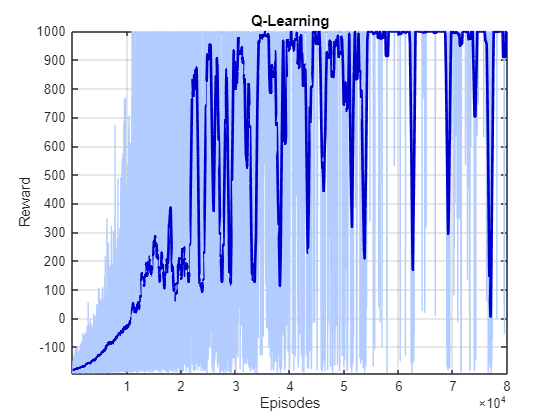


% Graph --> Q-LEARNING
figure('Name', 'Analisi Apprendimento', 'Color', 'w');

% plot of raw data (light blue)
plot(rewards_per_episode, 'Color', [0.7, 0.8, 1.0], 'HandleVisibility', 'off'); 
hold on;

% calculation and plot of the moving average (dark blue)
moving_avg = movmean(rewards_per_episode, 500); % Average over 500 episodes to clean up the graph
plot(moving_avg, 'Color', [0, 0, 0.8], 'LineWidth', 2, 'DisplayName', 'Trend (Media Mobile)');

title('Q-Learning');
xlabel('Episodes');
ylabel('Reward');
grid on;
axis tight;

OBS.

All parameters were chosen after numerous attempts that led us to what we believe are good values for solving this task:

- **Learning rate** ($\alpha =0\ldotp 05$): we chose a relatively low value, in order to prevent the `Q_table` values from fluctuating excessively based solely on individual updates

- **Discount factor** ($\gamma =0\ldotp 995$): as discussed in class, we set a discount factor very close to 1, since the goal is to remain in equilibrium for as long as possible. If we had a smaller $\gamma$, the agent would be more concerned with “immediate survival”, thus failing to predict that a certain action could lead to a fall in the next steps

- **Exploration** ($\epsilon$): we implemented a decay strategy of $\epsilon$. We start with a $\epsilon =1\ldotp 0$, i.e. maximum exploration, to ensure that the agent visits the entire state space in the first episodes. The decay rate is calculated so that $\epsilon$ reaches its minimum towards the end of training (at 85% of total episodes), thus ensuring a gradual transition from the exploration phase to the exploitation phase.

% TEST SUL Q-Learning
episodi_test = 50;
rewards_test = zeros(episodi_test, 1);

for ep = 1:episodi_test
        x_0 = stato_iniziale();                 % initial state
        idx_x_k = indiceStato(x_0);             % initial discrete index
        total_reward = 0;                       % total reward (inizialised at 0)
        
        % for cart and pole animation
        stati_tot = [];                         % buffer to store all the states of an episode
        stati_tot = [stati_tot, x_0];           % let's store the initial state
    
    for step = 1:max_steps
        
        % let's take the optimal policy
        [~, idx_azione_ottimale] = max(Q_table_opt(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), :));
     
        % simulation: apply force -> new state x_k_1
        [x_k_1, reward] = simulatore(x_0, idx_azione_ottimale, par, Ts, theta_limit, p_c_limit);
        idx_x_k_1 = indiceStato(x_k_1);
        total_reward = total_reward + reward;

        % store the state in the buffer for system animation
        stati_tot = [stati_tot, x_k_1];
        
        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
           break;
        end

        % state update
        idx_x_k = idx_x_k_1;
        x_0 = x_k_1;

        
    end

    rewards_test(ep) = total_reward;
        
    % if                    --> we need this to print only episodes that are multiples of 5
    % mean()                --> allows us to see how much we have earned in the last 5 episodes
    if mod(ep, 5) == 0
       avg_reward = mean(rewards_test((ep-4):ep));
    
       fprintf('Ep: %d/%d | Current Reward: %d | Average(5): %.1f | Step: %d \n',  ...
       ep, episodi_test, total_reward, avg_reward, step);
    end
end

Ep: 5/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 10/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 15/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 20/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 25/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 30/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 35/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 40/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 45/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 
Ep: 50/50 | Current Reward: 1000 | Average(5): 1000.0 | Step: 1000 


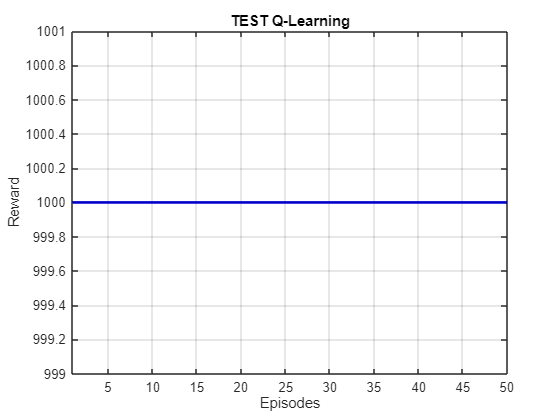

% Graph --> TEST Q-LEARNING 
figure('Name', 'Analisi Apprendimento', 'Color', 'w');

% plot of raw data (light blue)
plot(rewards_test, 'Color', [0.7, 0.8, 1.0], 'HandleVisibility', 'off'); 
hold on;

% calculation and plot of the moving average (dark blue)
moving_avg = movmean(rewards_test, 5); % Average over 5 episodes
plot(moving_avg, 'Color', [0, 0, 0.8], 'LineWidth', 2, 'DisplayName', 'Trend (Media Mobile)');

title('TEST Q-Learning');
xlabel('Episodes');
ylabel('Reward');
grid on;
axis tight;

Start video recording: animation_TEST_QL ...
Video saved as: animation_TEST_QL


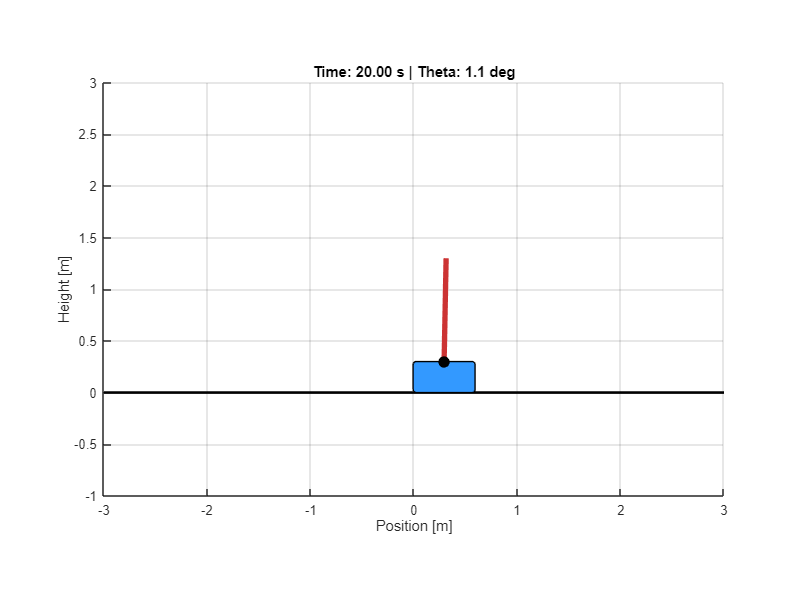


% Animation --> TEST Q-LEARNING
animazione_test(stati_tot, par, Ts, 'animation_TEST_QL');

OBS.

As we can see from the graph, the agent successfully learns the optimal policy, reaching the maximum reward of 1000. The "Test Q-Learning" graph, which shows a flat line at 1000, confirms that the *greedy policy* extracted from the Q-table is capable of stabilising the system up to the maximum number of steps. 

Since in each episode during the Q-Learning Test simulation the agent reaches the maximum reward, for reasons of ‘code execution time’ we have decided to provide the animation of only the last episode tested.

7. Copy and paste your Q-learning algorithm and apply the changes needed to convert it into a SARSA algorithm

**ANSWER 7:**

Let us recall the theory studied, in order to best present the following MATLAB code describing a *SARSA algorithm*:

**SARSA** is an ***On-Policy Algorithm***, which means that the evaluation is based on the *current policy*. 

INITIALISATION: the matrix is initialised $Q\;\;\;\;\forall x\in X\;\;\;\forall u\in U$

FOR EACH *EPISODE*, REPEAT THE FOLLOWING STEPS:

- set the initial state $x^{\left(0\right)}$

- select an action $u^{\left(k\right)}$ with $\varepsilon -\textrm{greedy}\;\textrm{policy}$

- repeat for each *step* of the episode until we encounter a terminal condition:

                  -    perform the action $u^{\left(k\right)}$, observe $x^{\left(k+1\right)}$ e $r^{\left(k+1\right)}$

                  -    select an action $u^{\left(k+1\right)}$ with $\varepsilon -\textrm{greedy}\;\textrm{policy}$

                  -    $Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)=Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)+\alpha \left\lbrack r^{\left(k+1\right)} +\gamma Q\left(x^{\left(k+1\right)} ,u^{\left(k+1\right)} \right)-Q\left(x^{\left(k\right)} ,u^{\left(k\right)} \right)\right\rbrack$   

                  -    update $x^{\left(k\right)} =x^{\left(k+1\right)} \;,u^{\left(k\right)} =u^{\left(k+1\right)}$  

% SARSA initialisation
eps = epsilon_start;
Q_table_sarsa = zeros(n_theta, n_theta_1, n_p_c, n_p_c_1, par.n_actions);
rewards_per_episode = zeros(num_episodes, 1);

% SARSA algorithm
for ep = 1:num_episodes
    x_0 = stato_iniziale();                % initial state
    idx_x_k = indiceStato(x_0);            % initial discete index
    total_reward = 0;
        
    % we choose the initial action with epsilon-greedy
        
    % action selection
    if rand < eps
       action_idx = randi(2);
    else
       [~, action_idx] = max(Q_table_sarsa(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), :));
    end
        
    for step = 1:max_steps
            
        % simulation: apply force -> new state x_k_1
        % perform the action, action_idx and observe:
        % 1. x_k_1
        [x_k_1, reward] = simulatore(x_0, action_idx, par, Ts, theta_limit, p_c_limit);
        idx_x_k_1 = indiceStato(x_k_1);
            
        % 2. reward_k_1 := reward
        total_reward = total_reward + reward;
            
        % we choose the next action with the epsilon greedy policy
        if rand < eps
           next_action_idx = randi(2);
        else
           [~, next_action_idx] = max(Q_table_sarsa(idx_x_k_1(1), idx_x_k_1(2), idx_x_k_1(3), idx_x_k_1(4), :));
        end

        % SARSA update
        sarsa_target = reward + gamma * Q_table_sarsa(idx_x_k_1(1), idx_x_k_1(2), idx_x_k_1(3), idx_x_k_1(4), next_action_idx);
        Q_table_sarsa(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), action_idx) = Q_table_sarsa(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), action_idx) + alpha * ( sarsa_target - Q_table_sarsa(idx_x_k(1), idx_x_k(2), idx_x_k(3), idx_x_k(4), action_idx));
            
        if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
           break;
        end

        % update the state and action for the next step
        idx_x_k = idx_x_k_1;
        x_0 = x_k_1;
        action_idx = next_action_idx;

                        
    end
        
    rewards_per_episode(ep) = total_reward;
        
    % epsilon decay
    eps = max(epsilon_min, eps * epsilon_decay);
        
    % print every 1000 episodes (as in Q-learning)
    if mod(ep, 1000) == 0
       avg_reward = mean(rewards_per_episode((ep-99):ep));
            
       fprintf('Ep: %d/%d | Epsilon: %.3f | Average(100): %.1f | Step: %d \n', ...
                     ep,num_episodes, eps, avg_reward, step);
    end
end

Ep: 1000/80000 | Epsilon: 0.903 | Average(100): -173.9 | Step: 40 
Ep: 2000/80000 | Epsilon: 0.816 | Average(100): -171.3 | Step: 26 
Ep: 3000/80000 | Epsilon: 0.737 | Average(100): -162.2 | Step: 28 
Ep: 4000/80000 | Epsilon: 0.666 | Average(100): -151.9 | Step: 102 
Ep: 5000/80000 | Epsilon: 0.602 | Average(100): -128.0 | Step: 40 
Ep: 6000/80000 | Epsilon: 0.544 | Average(100): -95.3 | Step: 14 
Ep: 7000/80000 | Epsilon: 0.491 | Average(100): -64.6 | Step: 401 
Ep: 8000/80000 | Epsilon: 0.444 | Average(100): -41.4 | Step: 379 
Ep: 9000/80000 | Epsilon: 0.401 | Average(100): 7.9 | Step: 249 
Ep: 10000/80000 | Epsilon: 0.362 | Average(100): 39.6 | Step: 138 
Ep: 11000/80000 | Epsilon: 0.327 | Average(100): 30.3 | Step: 163 
Ep: 12000/80000 | Epsilon: 0.296 | Average(100): 79.8 | Step: 889 
Ep: 13000/80000 | Epsilon: 0.267 | Average(100): 112.1 | Step: 503 
Ep: 14000/80000 | Epsilon: 0.241 | Average(100): 44.8 | Step: 173 
Ep: 15000/80000 | Epsilon: 0.218 | Average(100): 83.1 | Step: 8

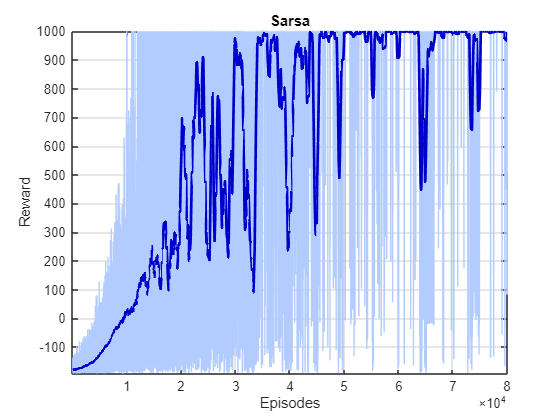


% Graph --> SARSA
figure('Name', 'Analisi Apprendimento', 'Color', 'w');

% plot of raw data (light blue)
plot(rewards_per_episode, 'Color', [0.7, 0.8, 1.0], 'HandleVisibility', 'off'); 
hold on;

% calculation and plot of the moving average (dark blue)
moving_avg = movmean(rewards_per_episode, 500); % Average over 500 episodes to clean up the graph
plot(moving_avg, 'Color', [0, 0, 0.8], 'LineWidth', 2, 'DisplayName', 'Trend (Media Mobile)');

title('Sarsa');
xlabel('Episodes');
ylabel('Reward');
grid on;
axis tight;

OBS.

The main difference between the SARSA algorithm and the Q-Learning algorithm lies in the Q-table update equation. While Q-Learning updates the estimate using the maximum possible reward of the next state ($\textrm{maxQ}\left(x^{\left(k+1\right)} ,u\right)$), SARSA updates using the actual action selected from the current policy (which includes exploration $\epsilon -\textrm{greedy}$), i.e.: $Q\left(x^{\left(k+1\right)} ,u^{\left(k+1\right)} \right)$.

The graph above confirms that SARSA also converges to the optimal solution, thus validating the effectiveness of both methods for solving this task.

**NOTE:**

*Local Functions* used in the above code, presented with appropriate comments:


% --- LOCAL FUNCTIONS ---
% % 1. indiceStato() --> allows us to assign each state variable the index of the interval in which it is contained.
%                     We then obtain a vector of integers representing the indexes of the intervals that
%                     contain the continuous value of the corresponding state variable.
%                     We will pass as parameters: 
%                       - x, state vector [4x1]

function idx_vec = indiceStato(x)
        % x = [theta, theta_1, p_c, p_c_1]

        % theta
        if     x(1) < deg2rad(-12)
            idx_theta = 1;
        elseif x(1) >= deg2rad(-12) && x(1) < deg2rad(-6)
            idx_theta = 2;
        elseif x(1) >= deg2rad(-6) && x(1) < deg2rad(-1)
            idx_theta = 3;
        elseif x(1) >= deg2rad(-1) && x(1) < deg2rad(1)
            idx_theta = 4;
        elseif x(1) >= deg2rad(1) && x(1) < deg2rad(6)
            idx_theta = 5;
        elseif x(1) >= deg2rad(6) && x(1) < deg2rad(12)
            idx_theta = 6;
        elseif x(1) >= deg2rad(12)
            idx_theta = 7;
        end

        % theta_1
        if     x(2) < -1.5
            idx_theta_1 = 1;
        elseif x(2) >= -1.5 && x(2) < -0.25
            idx_theta_1 = 2;
        elseif x(2) >= -0.25 && x(2) < 0.25
            idx_theta_1 = 3;
        elseif x(2) >= 0.25 && x(2) < 1.5
            idx_theta_1 = 4;
        elseif x(2) >= 1.5
            idx_theta_1 = 5;
            
        end

        % p_c
        if     x(3) < -2.4
            idx_p_c = 1;
        elseif x(3) >= -2.4 && x(3) < -0.8
            idx_p_c = 2;
        elseif x(3) >= -0.8 && x(3) < 0.8
            idx_p_c = 3;
        elseif x(3) >= 0.8 && x(3) < 2.4
            idx_p_c = 4;
        elseif x(3) >= 2.4
            idx_p_c = 5;
        end

        % p_c_1
        if     x(4) < -0.5
            idx_p_c_1 = 1;
        elseif x(4) >= -0.5 && x(4) < 0.5
            idx_p_c_1 = 2;
        elseif x(4) >= 0.5
            idx_p_c_1 = 3;
        end

        idx_vec = [idx_theta , idx_theta_1 , idx_p_c , idx_p_c_1];
end

% % 2. simulatore() --> allows us to simulate the system by providing us with
%                       the next state and the reward obtained by the agent. 
%                       We will pass the following parameters:
%                           - x, state vector [4x1] 
%                           - idx_action, action index (idx_action=1 --> F=-10, idx_action=2 --> F=10)
%                           - par, parameters for solving differential equations 
%                           - Ts, sampling time
%                           - theta_limit and p_c_limit, limits on angle and position
function [x_k_1, reward] = simulatore(x, idx_action, par, Ts, theta_limit, p_c_limit)
    
    % select the action
    par.F = par.actions(idx_action);
    
    % let's integrate the dynamics
    t_span = [0, Ts];

    options = odeset('RelTol', 1e-3, 'AbsTol', 1e-4);

    [~, x_k] = ode45(@(t,x) dinamica_nonLineare(t, x, par), t_span, x, options);
    x_k_1 = x_k(end, :)';
    
    % we check if a state is terminal and calculate the REWARD.
    % DEF. (Reward) --> The Reward in Reinforcement Learning (RL) is a scalar feedback signal, ∈ R, 
    %                   which indicates how well the controller is operating at step k.
    %                   The goal of RL is to learn a controller π capable of maximising the discounted cumulative reward.
    %
    % OBS.          --> The Reward we have implemented aims to evaluate the agent in different states, 
    %                   assigning +1 as long as it remains ‘alive’ (i.e., it does not exit the constraints), and -200 if it exits the constraints: 
    %                   in this way, we never leave our agent without knowing whether it is proceeding correctly or not, 
    %                   providing it with continuous feedback that allows Q-Learning to converge to the desired value.

    if condizioni_terminali(x_k_1, theta_limit, p_c_limit) == true
        
        reward = -200;    % Penality if you exit the constraints
    
    else
        
        reward = 1;       % Reward +1 for every step (success)
        
    end
end

% % 3. condizioni_terminali() --> allows us to check if we are outside the limits imposed to exit the simulation. 
%                                 We will pass as parameters: 
%                                   - x, state vector [4x1] 
%                                   - theta_limit, angle limits
%                                   - p_c_limit, position limits

function terminal = condizioni_terminali(x, theta_limit, p_c_limit)
    
    % let's check if the state is outside the defined limits
    fuori_ang = abs(x(1)) > theta_limit;
    fuori_pos = abs(x(3)) > p_c_limit;
    
    terminal = fuori_ang || fuori_pos;
end

% % 4. stato_iniziale() --> returns a random value around equilibrium, i.e. around [0, 0, 0, 0]. 
%                           We force the two speeds to zero, as it is plausible that the system to be stationary in its initial state. 

function x0 = stato_iniziale()
    
    % we return a random initial state close to equilibrium
    x0 = (rand(4,1) - 0.5) * 0.1;
    
    % we force the speeds to zero, as it is plausible that 
    % the system is stationary in its initial state
    x0(2) = 0;
    x0(4) = 0;

end

% % 5. dinamica_nonLineare() --> allows us to calculate x_dot, through the implementation
%                                of the nonlinear differential equations of the Cart-and-Pole system. 
%                                The parameters we will pass are:
%                                   - t, not used explicitly in the function, is used to call ode()
%                                   - x, state vector [4x1]
%                                   - par, a structure containing all useful parameters

function dxdt = dinamica_nonLineare(t, x, par)

% extraction of parameters and state
g = par.g;
m_c = par.m_c;
m_p = par.m_p;
l = par.l;
mu_c = par.mu_c;
mu_p = par.mu_p;
F = par.F;

theta    = x(1);
theta_1  = x(2);
p_c      = x(3);
p_c_1    = x(4);

% let's define, therefore, theta_2 e p_c_2
theta_2 = ( g*sin(theta)+cos(theta)*((-F-m_p*l*(theta_1^2)*sin(theta)+mu_c*sign(p_c_1))/(m_c+m_p))-(mu_p*theta_1)/(m_p*l) ) / ( l * ((4/3)-(m_p*(cos(theta)^2))/(m_c+m_p) ));
p_c_2 = ( F+m_p*l*((theta_1^2)*sin(theta)-(theta_2)*cos(theta))-mu_c*sign(p_c_1) )/ (m_c+m_p);


% let's define the derivate vector dxdt
% dxdt = [theta_1; theta_2; p_c_1; p_c_2]
dxdt = zeros(4, 1);

dxdt(1) = theta_1;
dxdt(2) = theta_2;
dxdt(3) = p_c_1;
dxdt(4) = p_c_2;

end

% % 6. animazione_test() --> allows us to describe the animation of the cart-and-pole system, 
%                            thus providing visual support in addition to the graphs.
%                            It only shows the last moment in time, but this function allows us to save the various frames
%                            in a video, so that we can see the entire simulation
%                            The parameters we pass to it are:
%                               - stati, a vector containing all states 
%                               - par, a struct containing all useful parameters
%                               - Ts, sampling time
%                               - video_filename, the name we saved the video file with

function animazione_test(stati, par, Ts, video_filename)
    
    % graphical parameters
    L = 2 * par.l;          
    W_cart = 0.6;           
    H_cart = 0.3;           
    
    % let's create the figure
    h_fig = figure('Name', 'Animazione Cart-Pole', 'Color', 'w');
    set(h_fig, 'Position', [100, 100, 800, 600]); 
    clf;
    hold on;
    grid on;
    axis equal;
    xlim([-3, 3]);          
    ylim([-1, 3]); 

    % let's create the 'floor'
    line([-3, 3], [0, 0], 'Color', 'k', 'LineWidth', 2);

    % create a video file in the current folder
    v = VideoWriter(video_filename, 'MPEG-4');
    v.FrameRate = 1/Ts; 
    open(v);
    fprintf('Start video recording: %s ...\n', video_filename);
    
    % let's draw the Initial Condition
    theta0 = stati(1, 1);
    pos0   = stati(3, 1);
    
    % calculation of initial coordinates
    cart_x0 = pos0 - W_cart / 2;
    base_x0 = pos0;
    base_y0 = H_cart;
    punta_x0 = base_x0 + L * sin(theta0);
    punta_y0 = base_y0 + L * cos(theta0);

    % drawing stationary objects
    % OSS. --> - rectangle(), for the cart
    %          - line(), for the pole
    %          - plot(), for the joint, i.e. the junction between them
    h_cart = rectangle('Position', [cart_x0, 0, W_cart, H_cart], 'FaceColor', [0.2, 0.6, 1], 'Curvature', 0.2);
    h_pole = line([base_x0, punta_x0], [base_y0, punta_y0], 'Color', [0.8, 0.2, 0.2], 'LineWidth', 4);
    h_joint = plot(base_x0, base_y0, 'ko', 'MarkerFaceColor', 'k', 'MarkerSize', 8);
    
    title_handle = title('Generazione Video in corso... ');
    xlabel('Position [m]');
    ylabel('Height [m]');
   

    % Animation Cycle
    n_steps = size(stati,2);

    for k = 1:n_steps
        
        theta = stati(1, k);
        pos   = stati(3, k);
        
        % Coordinate update
        cart_x = pos - W_cart / 2;   
        set(h_cart, 'Position', [cart_x, 0, W_cart, H_cart]);
        
        base_x = pos;
        base_y = H_cart;
        punta_x = base_x + L * sin(theta);
        punta_y = base_y + L * cos(theta);
        
        set(h_pole, 'XData', [base_x, punta_x], 'YData', [base_y, punta_y]);
        set(h_joint, 'XData', base_x, 'YData', base_y);
        
        set(title_handle, 'String', sprintf('Time: %.2f s | Theta: %.1f deg', (k-1)*Ts, rad2deg(theta)));
        
        % command for drawing the cart-and-pole
        drawnow; 
       
        % FRAME capture and frame loading (in the video)
        frame = getframe(h_fig);
        writeVideo(v, frame);
    end
    
    % Close and save the video file
    close(v);
    fprintf('Video saved as: %s\n', video_filename);
end